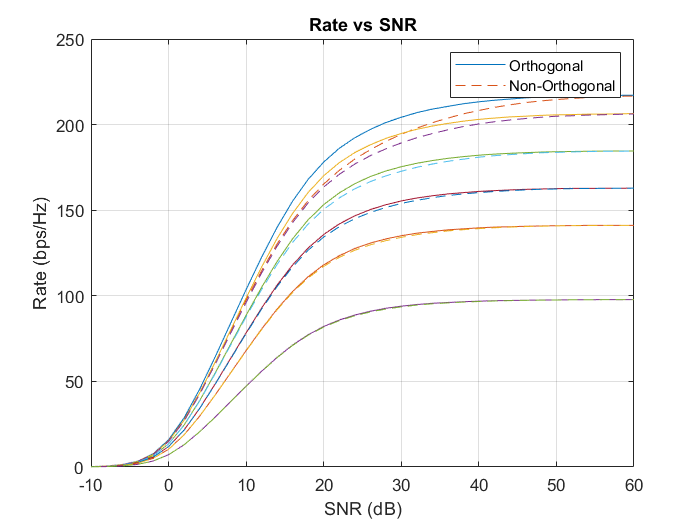

T       = [40 48 64 80 96 128];     % Lenght of Pilot Sequence
SNR_dB  = (-10:2:60);               % SNR in dB

figure(1)
for i=1:length(T)
    plot(SNR_dB,Rate_O(:,i)')
    hold on
    plot(SNR_dB,Rate_No(:,i)','--')
    hold on
end
grid on
title( 'Rate vs SNR')
xlabel('SNR (dB)')
ylabel('Rate (bps/Hz)')
legend('Orthogonal','Non-Orthogonal')

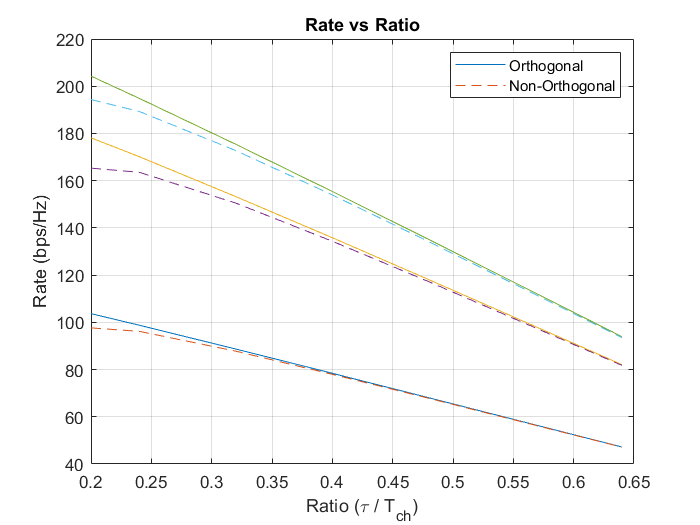


figure(3)
for i=1:length(SNR_dB)
    if (SNR_dB(i) == 10) || (SNR_dB(i) == 20) || (SNR_dB(i) == 30)
        plot((T/T_ch),Rate_O(i,:))
        hold on
        plot((T/T_ch),Rate_No(i,:),'--')
        hold on
    end
end
grid on
title( 'Rate vs Ratio')
xlabel('Ratio (\tau / T_{ch})')
ylabel('Rate (bps/Hz)')
legend('Orthogonal','Non-Orthogonal')